close all; clc; clear;
%% Параметры антенн
htx         = 5;        % in meters
hrx         = 1000;     % in meters
fc          = 2.4e9;    % in Hz

%% Карта, параметры приёмника и передатчика
viewer = siteviewer("Buildings","map_2.osm"); %map_2 Карта Ильи, Лахта
txLat = 59.98861; txLong  = 30.129038;

% Координаты приёмника: расстояние, широта, долгота
% 100m 59.987729, 30.128985
% 500m 59.984149, 30.128749
% 1000m 59.979587, 30.128362
% 5000m 59.944063, 30.120881
% 10e3m 59.958733, 29.959647
% 20e3m 59.958733, 29.959647

rxLats = [59.987729 59.984149 59.979587 59.944063 59.958733 59.958733];
rxLongs = [30.128985 30.128749 30.128362 30.120881 29.959647 29.959647]; 

h = [10 50 100 500 1000]; % in meters
d = [100 500 1000 5000 10e3 20e3]; % in meters

%% Структура с параметрами лучей 
RaysStruct = {};

%% Передатчик
tx = txsite("Latitude", txLat, "Longitude", txLong, ...
    "AntennaHeight", htx,"TransmitterPower", 100e-3, ...
    "TransmitterFrequency", fc);


%% Таблица
RaysTable = table('Size', [length(h), length(d)],...
'VariableTypes', ["cell", "cell", "cell", "cell", "cell", "cell"], ...
'VariableNames', ["Distance = 100", "Distance = 500", "Distance = 1000", "Distance = 5000", "Distance = 10e3", "Distance = 20e3"],...
'RowNames', ["RX height = 10"; "RX height = 50"; "RX height = 100"; "RX height = 500"; "RX height = 1000"]);

for h_ind = 1:length(h)
    for d_ind = 1:length(d)

        % Приёмник 
        rx = rxsite("Latitude", rxLats(d_ind), "Longitude", rxLongs(d_ind), ...
            "AntennaHeight", h(h_ind), ...
            "ReceiverSensitivity", -100);

        % Расстояние в км между приёмником и передатчиком 
        realDist (h_ind, d_ind) = distance(rx,tx)/1e3; % in km

        pm = propagationModel("raytracing", ...
        "Method", "sbr", ...
        "MaxNumReflections", 2, ...
        "MaxNumDiffractions", 1, ...
        "MaxRelativePathLoss", 40, ...
        "TerrainMaterial", "Loam");
       
        % Мощность сигнала на приёмнике, в дБ
        signalStrength (h_ind, d_ind) = sigstrength(rx,tx,pm);
        margin(h_ind, d_ind) = abs(rx.ReceiverSensitivity - signalStrength(h_ind, d_ind));

        RaysTable.(d_ind){h_ind} = raytrace(tx,rx,pm, "Type", "pathloss");
        
        %RaysStruct(h_ind, d_ind) = raytrace(tx,rx,pm, "Type", "pathloss");
        
        % Пример как обращаться: (h=1000, d = 10, 2й луч), фазовый сдвиг
        % RaysStruct{find(h == 1000), find(d == 10)}(1,2).PhaseShift

    end
end


## Построение графиков

% Найдём максимальный и минимальный фазовый сдвиг луча для каждого значения h, d 
maxPhaseShift = zeros (length(h), length(d));
minPhaseShift =  zeros (length(h), length(d));
for h_ind = 1:length(h)
    for d_ind = 1:length(d)
        numRays = length(RaysTable.(d_ind){h_ind,1}{1,1});
        for cnt = 1:numRays
            rayPhaseShifts(cnt,:) = RaysTable.(d_ind){h_ind,1}{1, 1}(1,cnt).PhaseShift;
        end
        maxPhaseShift(h_ind, d_ind) = max(rayPhaseShifts);
        minPhaseShift(h_ind, d_ind) = min(rayPhaseShifts);
        rayPhaseShifts = [];
    end
end


% График максимальных потерь при распространении луча для каждого значения h,d
maxPathLoss = zeros (length(h), length(d));
%minPathLoss =  zeros (length(h), length(d));
for h_ind = 1:length(h)
    for d_ind = 1:length(d)
        numRays = length(RaysTable.(d_ind){h_ind,1}{1,1});
        for cnt = 1:numRays
            rayPathLoss(cnt,:) = RaysTable.(d_ind){h_ind,1}{1, 1}(1,cnt).PathLoss;
        end
        maxPathLoss(h_ind, d_ind) = max(rayPathLoss);
        %minPhaseShift(h_ind, d_ind) = min(rayPhaseShifts);
        rayPhaseShifts = [];
    end
end

% Информация по лучу прямой видимости для каждого знаечния h, d
lineOfSightData = table('Size', [length(h), length(d)],...
'VariableTypes', ["cell", "cell", "cell", "cell", "cell", "cell"], ...
'VariableNames', ["Distance = 100", "Distance = 500", "Distance = 1000", "Distance = 5000", "Distance = 10e3", "Distance = 20e3"],...
'RowNames', ["RX height = 10"; "RX height = 50"; "RX height = 100"; "RX height = 500"; "RX height = 1000"]);

for h_ind = 1:length(h)
    for d_ind = 1:length(d)
        numRays = length(RaysTable.(d_ind){h_ind,1}{1,1});
        for cnt = 1:numRays
            if RaysTable.(d_ind){h_ind,1}{1, 1}(1,cnt).LineOfSight == 1
                lineOfSightData.(d_ind){h_ind} = RaysTable.(d_ind){h_ind,1}{1, 1}(1,cnt);
                break
            end 
        end
    end
end


% График зависимости максимального фазового сдвига от уровня приёмника и
% расстояния между приёмником и передатчиком
figure (1)
phaseShiftmap = heatmap(maxPhaseShift, XLabel = 'Distance b/w RX and TX, m',...
    YLabel = 'Receiver height, m',...
    XDisplayLabels = d,...
    YDisplayLabels = h,...
    Title = 'Maximum phase shifts in radians, transmitter height = 5m')

phaseShiftmap =   HeatmapChart (Maximum phase shifts in radians, transmitter height = 5m) with properties:

        XData: {6×1 cell}
        YData: {5×1 cell}
    ColorData: [5×6 double]

  Show all properties



% График зависимости минимального фазового сдвига от уровня приёмника и
% расстояния между приёмником и передатчиком
figure (2)
phaseShiftmap = heatmap(minPhaseShift, XLabel = 'Distance b/w RX and TX, m',...
    YLabel = 'Receiver height, m',...
    XDisplayLabels = d,...
    YDisplayLabels = h,...
    Title = 'Minimum phase shifts in radians, transmitter height = 5m')

phaseShiftmap =   HeatmapChart (Minimum phase shifts in radians, transmitter height = 5m) with properties:

        XData: {6×1 cell}
        YData: {5×1 cell}
    ColorData: [5×6 double]

  Show all properties


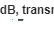

phaseShiftmap =   HeatmapChart (Maximum path loss in dB, transmitter height = 5m) with properties:

        XData: {6×1 cell}
        YData: {5×1 cell}
    ColorData: [5×6 double]

  Show all properties



% График зависимости максимальных потерь распространения от уровня приёмника и
% расстояния между приёмником и передатчиком
figure (3)
phaseShiftmap = heatmap(maxPathLoss, XLabel = 'Distance b/w RX and TX, m',...
    YLabel = 'Receiver height, m',...
    XDisplayLabels = d,...
    YDisplayLabels = h,...
    Title = 'Maximum path loss in dB, transmitter height = 5m');